Esercizio 1.

Genero un numero intero divisibile per 4 compreso tra 1 e 40

% Non ha senso generare n numeri e controllare che siano divisibili per 4 quando posso fare questo
n = 4 * randi([1, 10], 1);

**La traccia d'esame dice di fare m come n/4, ma così D uscirebbe 2m x 2m, non n x n, sarebbe grande la metà e non avrebbe senso.**

% Traccia errata!!!!!!!!!!!!!!!
m = n / 2;

Costruisco le 4 matrici che comporranno D:

D1 = -1 * ones(m);
D2 = -2 * ones(m);
D3 = -3 * ones(m);
D4 = -4 * ones(m);

D = [D1, D2;
     D3, D4]

D =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2    -2
    -1    -1    -1    -1    -1  


z = 3 * ones(n, 1)

z =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


y = D * z

y =   -180
  -180
  -180
  -180
  -180
  -180
  -180
  -180
  -180
  -180


clc
clear

Esercizio 2.

Creo la matrice dei coefficienti A

A = 4 * rand(20) - 2;
% Privo A della sua diagonale
A = A - diag(A);
% E successivamente le assegno il valore desiderato, solo nella diagonale
A(1 : 21 : end) = 100 * ones(1, 20);

Ax = b, x = [-2, ..., -2]

x = -2 * ones(20, 1);
b = A * x;

x0 = zeros(20, 1);
[x1, k1] = gauss_seidel(A, b, x0, 10e-5, 100);

err = norm(x1 - x) / norm(x);

disp("È stata trovata la soluzione ");

È stata trovata la soluzione 


x1

x1 =    -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000
   -2.0000


disp("dopo " + k1 + " iterazioni con errore " + err);

dopo 4 iterazioni con errore 1.6627e-06


clc
clear

Esercizio 3.

Equazione

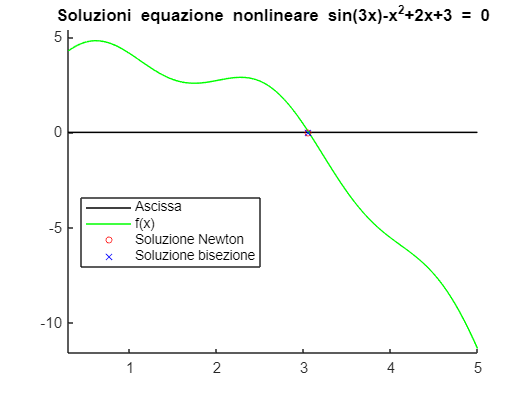

f = @(x) sin(3 .* x) - x .* x + 2 .* x + 3;
fder = @(x) 3 .* cos(3 .* x) - 2 .* x + 2;

[xn, kn] = newton(f, fder, 1, 10e-5, 100);
[xb, kb] = bisezione(f, 0, 4, 10e-5, 100);

x = linspace(0, 5, 100);
figure;
hold on;

title("Soluzione equazione nonlineare sin(3x)-x^2+2x+3 = 0");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "Or", "DisplayName","Soluzione Newton", "MarkerSize", 4);
plot(xb, f(xb) , "xb", "DisplayName","Soluzione bisezione", "MarkerSize", 6);

legend("Location", "best");

hold off;

function [x, k] = gauss_seidel(A, b, x0, tau, k_max)

    % tau e k_max sono le condizioni di stop:
        % tau = tolleranza
        % k_max = iterazioni massime
    
    if (nargin > 5)
        error("Sono stati inseriti troppi parametri in input");
    end
    
    % Check se matrice è singolare o meno
    if (abs(det(A)) < 1e-12)
        error("Il sistema può non ammettere soluzioni");
    end
    
    % Nel caso la funzione jacobi venga chiamata con meno parametri, allora
    % imposto manualmente i parametri tagliati fuori
    
    if (nargin < 5)
        k_max = 1000;
    end
    
    if (nargin < 4)
        tau = 1e-14;
    end
    
    if (nargin < 3)
        x0 = zeros(size(A, 1), 1);
        x0(1) = 1;
    end
    
    % A = D + E + F
    
    % diag restituisce vettore, quindi doppio diag rende matrice con tutti 0 e diagonale estratta
    D = diag(diag(A));
    
    %E = (tril(A) - D) * -1; la scrittura di sotto è più efficiente
    E = -tril(A, -1);
    
    F = -triu(A, 1);
    
    %Bgs = (D - E)^-1 * F; la scrittura di sotto è più efficiente
    Bgs = (D - E) \ F;
    
    %fgs = (D - E)^-1 * b; la scrittura di sotto è più efficiente
    fgs = (D - E) \ b;
    
    % Un MLS1 converge quando il rho è < 1
    rho = abs(eigs(Bgs, 1, 'largestabs')); % anche con largestabs restituisce l'autovalore col suo segno originario
    
    if (rho >= 1)
        error("Il metodo non converge");
    end
    
    x_old = x0;
    flag = true;
    k = 1;
    while (flag)
        if (k >= k_max)
            warning("k_max è stato raggiunto");
            break;
        end
    
        x_new = Bgs * x_old + fgs;
    
        if (norm(x_new - x_old) < tau * norm(x_new))
            flag = false;
        else
            x_old = x_new;
            k = k + 1;
        end
    end
    
    x = x_new;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)
    kn = 1;
    xn = -1;
    f1 = fder(x0);

    if(abs(f(x0)) < tau)
        xn = x0;
        return;
    end

    while(kn < kmax && abs(f(xn)) >= tau)
        
        if(abs(f1) < tau)
            error("Cambia x0");
        end

        xn = x0 - f(x0) / f1;
        
        x0 = xn;
        f1 = fder(x0);

        kn = kn + 1;
    end
end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    kb = 1;
    xb = -1;
    fxb = -1;

    fa = f(a);
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [" + a, + ", " + b + "]");
    end

    while(kb < kmax && abs(fxb) >= tau)
       
        xb = (a + b) / 2;
        
        fxb = f(xb);
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end


        kb = kb + 1;
    end
end